# RBE 501: Coding Forward Kinematics in Robotics Toolkit

## *Build Denso's HSR robot with Robotics Toolkit*

First, we define joint variables.

theta1 = 0;
theta2 = 0;
d3 = 0;
theta4 = 0;

Now, we can import the DH params from the prompt of the assignment.

dhparams = [205   	0   	220   	theta1;
            275	    0       0       theta2;
            0   	0	    d3	    0;
            0       0       0       theta4];

Next, we create a rigid body tree object to build the Denso HSR robot. This is necessary to begin assigning rigid bodies (links) of the robot, to represent moving parts.

denso_robot = rigidBodyTree;

We can begin building the robot now. We make sure that the order of the joints is revolute, revolute, prismatic, revolute. This is because, as shown in the information web-page of Denso Robotics, the HSR robot is essentially a SCARA robot with a revolute tool-tip.

Furthermore, as described in the tutorial of the Robotics Toolkit, we need to assign bodies and joints, and then set their transforms (this is done by using rows of the DH table we are given). Joints also need to be associated with their bodies. Finally, bodies can be assigned to the rigid-body tree.

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

addBody(denso_robot,body1,'base')
addBody(denso_robot,body2,'body1')
addBody(denso_robot,body3,'body2')
addBody(denso_robot,body4,'body3')

We can verify that our robot was built correctly by showing its details.

showdetails(denso_robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


Optionally, it is also possible to show a graphic-visual respresentation of the robot. This is left as an optional section that only needs to be run if desired.

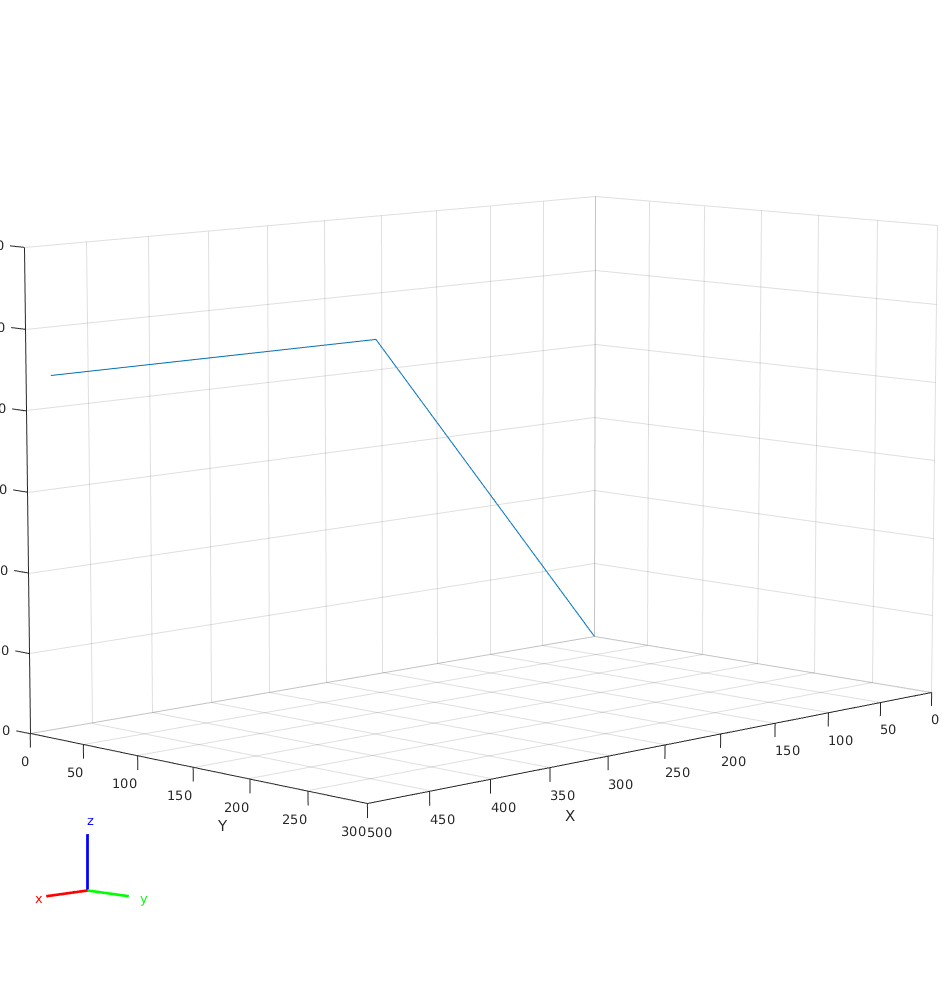

show(denso_robot);
axis([0,500,0,300,0,300])
axis on